# Matias Hiillos

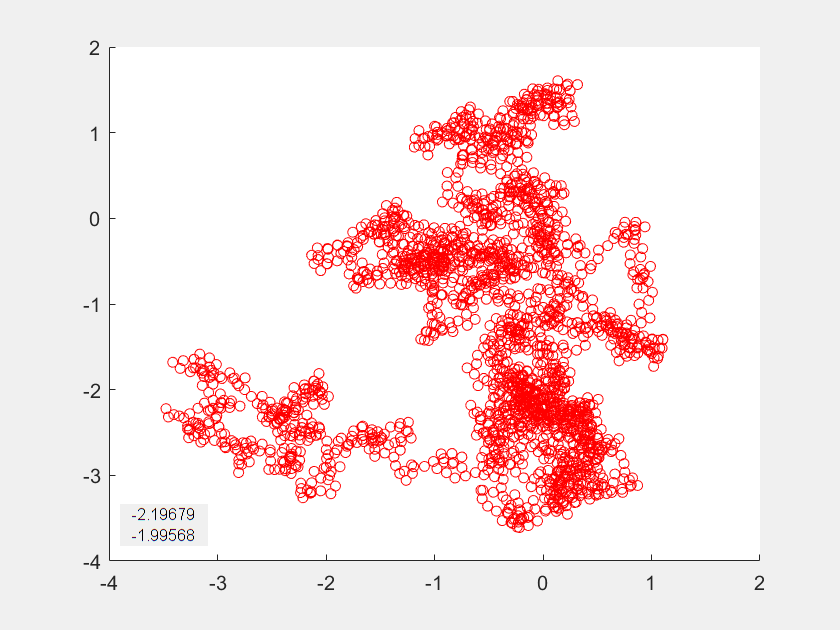

fh=figure('visible','on');
xo = 0; yo = 0;
h = animatedline(xo, yo, 'LineStyle', 'none', 'Marker', 'o',...
    'MarkerSize', 5, 'MaximumNumPoints', Inf, 'Color', [1 0 0]);
hx = uicontrol ('Style', 'text', 'Units', 'char' ,...
    'Position', [15 5 11 1]);
hy = uicontrol ('Style', 'text', 'Units', 'char' ,...
    'Position', [15 4 11 1]);

axis([-1 1 -1 1])

fh.UserData = true;
fh.WindowButtonDownFcn = @(hObject, event) set(hObject, 'UserData', false);

while fh.UserData
        theta=rand*2*pi;
        x = xo+0.1.*cos(theta);
        y = yo+0.1.*sin(theta);
        addpoints(h, x, y);
        drawnow
        
        hx.String=x;
        hy.String=y;
        
        axesh = gca;
        if ( axesh.XLim(1) > x )
            axesh.XLim(1) = axesh.XLim(1)-1;
        elseif (axesh.XLim(2) < x )
            axesh.XLim(2) = axesh.XLim(2)+1;
        end
        if ( axesh.YLim(1) > y )
            axesh.YLim(1) = axesh.YLim(1)-1;
        elseif ( axesh.YLim(2) < y )
            axesh.YLim(2) = axesh.YLim(2)+1;
        end
        
        xo = x; yo = y;
end